##  Two Degree-of-freedom Nonlinear Spring-Mass-Damper Model

clear
syms u1(t)
syms u2(t)
m1 = 29.485; m2 = 6.8; k1 = 11.912e3; k2 = 250e3; c1 = 23.71e3; c2 = 4e3;
ke = 40e3; ce = 75e3;

[V] = odeToVectorField(diff(u1, 2) == -9.81 -(c1*(diff(u1)-diff(u2))+k1*(u1-u2))/m1,...
    diff(u2,2) == -9.81 -(c1*(diff(u2)-diff(u1))+c2*diff(u2)+ce*(diff(u2)).^3+k1*(u2-u1)+(k2+ke)*u2)/m2)

$$V = \left(\begin{array}{c} Y_{2}\\ -\frac{187500\,{Y_{2}}^{3}}{17}-4075\,Y_{2}-\frac{754780\,Y_{1}}{17}+\frac{29780\,Y_{3}}{17}+\frac{59275\,Y_{4}}{17}-\frac{981}{100}\\ Y_{4}\\ \frac{2382400\,Y_{1}}{5897}+\frac{4742000\,Y_{2}}{5897}-\frac{2382400\,Y_{3}}{5897}-\frac{4742000\,Y_{4}}{5897}-\frac{981}{100} \end{array}\right)$$


M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);Y(2).^3.*(-1.102941176470588e+4)-Y(1).*4.439882352941176e+4-Y(2).*4.075e+3+Y(3).*1.751764705882353e+3+Y(4).*3.486764705882353e+3-9.81e+2./1.0e+2;Y(4);Y(1).*4.040020349330168e+2+Y(2).*8.04137697134136e+2-Y(3).*4.040020349330168e+2-Y(4).*8.04137697134136e+2-9.81e+2./1.0e+2]



sol = ode45(M,[0 16],[50 0 0 0]);
t = sol.x;
y = sol.y;
u1 = y(1,:);
u2 = y(3,:);
mean(u1)

ans = 28.4594

mean(u2)

ans = 15.5133

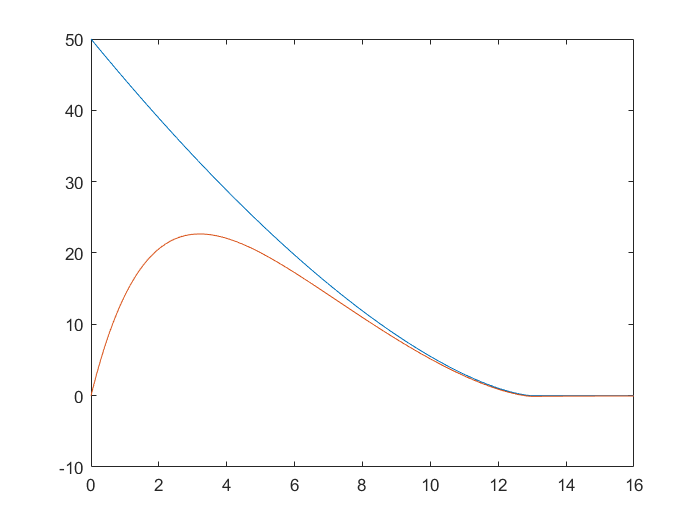

figure
plot(t,y(1,:), t,y(3,:))

u1_test = u1(:,5:21765:length(u1));
u2_test = u2(:,5:21765:length(u1));
t_test = t(:,5:21765:length(u1));

u1_train = u1(:,1:87062:length(u1));
u2_train = u2(:,1:87062:length(u2));
t_train = t(:,1:87062:length(t));

f_train = 0.1*rand(20,2) - 0.05;
t_f_train = 16.*rand(20,1);
t_f_train = sort(t_f_train);

t_test = t_test';
t_train = t_train';
u1_train = u1_train';
u1_test = u1_test';
u2_train = u2_train';
u2_test = u2_test';

u_test = [u1_test, u2_test];
u_train = [u1_train, u2_train];
save('Spring_mass_damper_model.mat','t_test','t_train','u_test','u_train','t_f_train','f_train');

### Lotka-Volterra model (preys & predators)

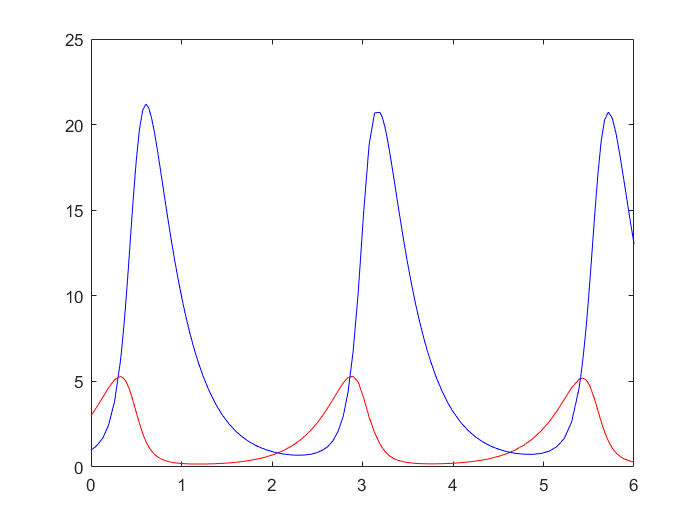

clear
o1 = 3; o12 = 0.5; o21 = 2; o2 = 3;
f = @(t,x) [o1*x(1) - o12*x(1).*x(2); o21*x(1).*x(2) - o2*x(2)];
[t,y] = ode45(f,[0 6],[3 1]);

t_test = t(2:2:length(t),:);
t_train = t(1:5:length(t),:);

u_test = y(2:2:length(t),:);
u_train = y(1:5:length(t),:);

meno_u = [];
meno_t = [];
sol = [];
for i = 1:length(t_train)-1
    meno_t = [meno_t t_train(i+1) - t_train(i)];
    meno_u = [meno_u; u_train(i+1,:) - u_train(i,:)];
    sol = [sol, f(t_train(i+1), u_train(i+1,:))];
end
meno_t = meno_t';
du = (meno_u)./(meno_t);
clear meno_t meno_u;
sol = sol';

%t_f = t_train(2:end);
%f_train = du - sol(:,:);
t_f_train = 6.*rand(25,1);
t_f_train = sort(t_f_train);
f_train = 0.1*rand(25,2) - 0.05;
save('Preys_predators_model.mat','t_test','t_train','u_train','u_test','t_f_train','f_train');
plot(t,y(:,1),'-r',t,y(:,2),'-b')

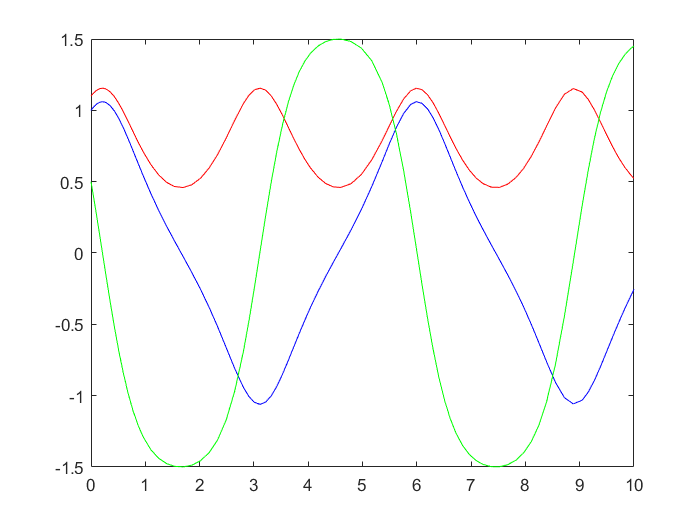

clear;
a = 1; b = 1;
f = @(t,x) [a*x(2).*x(3); b*x(1).*x(3); -(a+b)*x(1).*x(2)];
[t,y] = ode45(f,[0 10],[1.1 1 0.5]);

t_u_test = t(1:7:length(t),:);
u_test = y(1:7:length(t),:);
t_f_train = t(2:6:length(t),:);
f_train = y(2:6:length(t),:);
t_train = t;
u_train = y;
save('myKO.mat','t_train','t_u_test','u_test','u_train','t_f_train','f_train');

plot(t,y(:,1),'-r',t,y(:,2),'-b',t,y(:,3),'-g')

## Van Der Pol oscillator

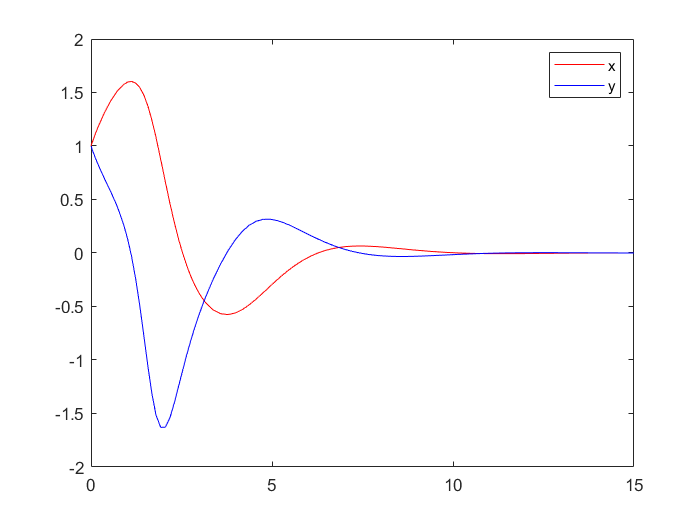

clear
mu = -1.2;
f = @(t,x) [x(2); mu*(1-x(1).^2).*x(2)-x(1)];
[t,y] = ode45(f,[0 15],[1 1]);
t_test = t(1:3:length(t),:);
u_test = y(1:3:length(t),:);
t_train = t(3:4:length(t),:);
u_train = y(3:4:length(t),:);
f_train = 0.1*rand(20,2) - 0.05;
t_f_train = 16.*rand(20,1);
t_f_train = sort(t_f_train);
save('VanDerPol.mat','t_train','t_test','u_test','u_train','t_f_train','f_train');

close
figure
plot(t,y(:,1),'-r',t,y(:,2),'-b')
legend('x', 'y')

## Duffing equation

clear
syms x(t);
gamma = 3; omega = 1; sigma = 0.02; a = 1; b= 1;
[V] = odeToVectorField(diff(x, 2) == gamma*cos(omega*t) - sigma*diff(x) - a*x - b*x.^3)

$$V = \left(\begin{array}{c} Y_{2}\\ -{Y_{1}}^{3}-Y_{1}+3\,\cos\left(t\right)-\frac{Y_{2}}{50} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);cos(t).*3.0-Y(1).^3-Y(1)-Y(2)./5.0e+1]


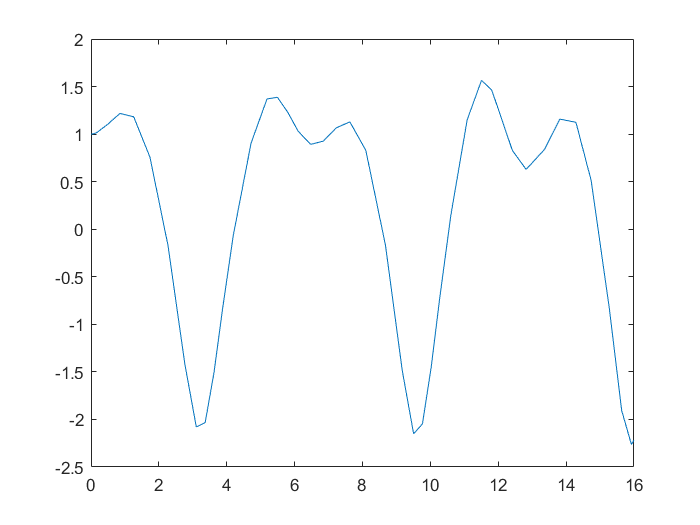

sol = ode45(M,[0 16],[1 0]);
t = sol.x;
y = sol.y;
u = y(1,:);
t_train = t(:,1:5:length(t));
u_train = u(:,1:5:length(t));
t_test = t(:,1:2:length(t));
u_test = u(:,1:2:length(t));
t_f_train = 6.*rand(20,1);
t_f_train = sort(t_f_train);
f_train = 0.1*rand(20,1) - 0.05;
save('Duffing.mat','t_test','t_train','u_train','u_test','t_f_train','f_train');
plot(t,u)

## 3 Species Preys and Predators


$$$\begin{cases}
\frac{du_1}{dt} = u_1(\mu-0.1\,u_1-0.5\,u_2-0.5\,u_3)\\
\frac{du_2}{dt} = u_2(-\mu+0.5\,u_1-0.3\,u_3)\\
\frac{du_3}{dt} = u_3(-\mu+0.2\,u_1+0.5\,u_2)\\
u_i = 0.5\;\;\;\forall\;i\,\in\,\left\{1,\,2,\,3\right\}
\end{cases}$$$


[https://arxiv.org/pdf/2201.10215.pdf](https://arxiv.org/pdf/2201.10215.pdf)

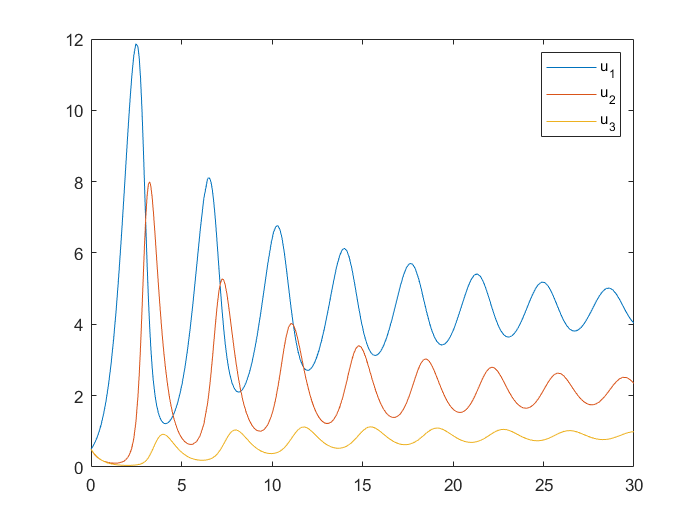

clear
mu = 1.95;
r1 = 0.5
f = @(t,x) [x(1).*(mu-0.1*x(1)-0.5*x(2)-0.5*x(3));...
    x(2).*(-mu+0.5*x(1)-0.3*x(3));... 
    x(3).*(-mu+0.2*x(1)+0.5*x(2))];
T = 30;
[t,y] = ode45(f,[0 T],[0.5 0.5 0.5]);
figure
plot(t,y)
legend('u_1', 'u_2', 'u_3')

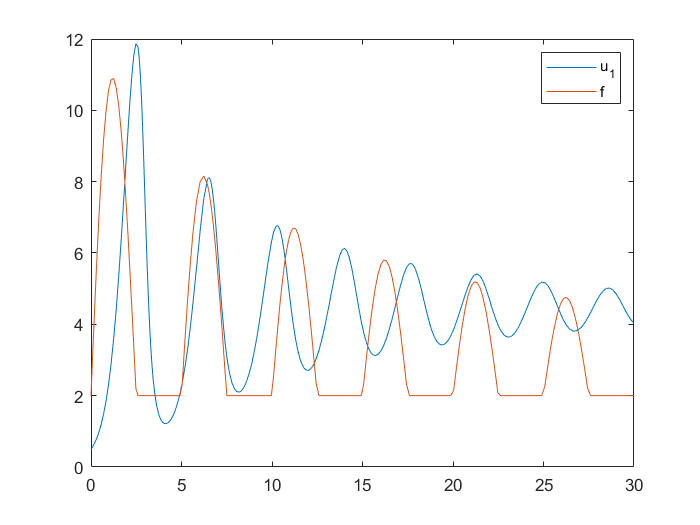

t_test = t(2:2:length(t),:);
t_train = t(1:5:length(t),:);

u_test = y(2:2:length(t),:);
u_train = y(1:5:length(t),:);

t_f_train = linspace(0,T,T*2)';
f_train = zeros(T*2, 3);
f_test = zeros(length(u_test),3);
if T == 10
    save('3_species.mat','t_test','t_train','u_train','u_test','t_f_train','f_train','f_test');
else
    save('3_species_30.mat','t_test','t_train','u_train','u_test','t_f_train','f_train','f_test');
end

f = @(x) heaviside(10*sin(2*pi*x/5))*10.*sin(2*pi*x/5)./(1+x/10) + 2;
figure
plot(t,y(:,1), t,f(t))
legend('u_1', 'f')

p = polyfit(t,y(:,1),T);

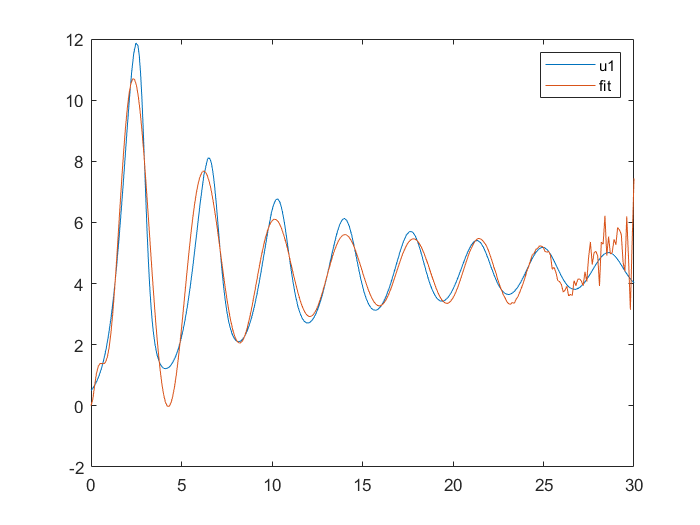

tt = linspace(0,T,T*10);
yy = polyval(p,tt);
figure
plot(t,y(:,1), tt,yy)
legend('u1','fit')

#### Inverse Poisson bpinn

clear
syms u(x)
D = 0.01;
k = 0.8;
% D * u_xx + k * tf.tanh(u)
[V] = odeToVectorField(diff(u, 2) == -k/D*tanh(u))

$$V = \left(\begin{array}{c} Y_{2}\\ -80\,\tanh\left(Y_{1}\right) \end{array}\right)$$

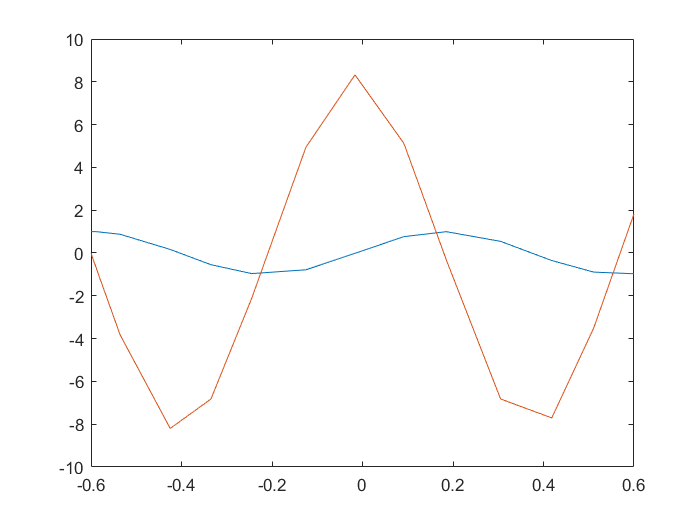

M = matlabFunction(V,'vars', {'t','Y'});
sol = ode45(M,[-0.6 0.6],[1 0]);
t = sol.x;
y = sol.y;
plot(t,y)

## Burger

syms u(x);
u0 = 0;
T = 1;
dt = 0.1;
[V] = odeToVectorField(diff(u, 2) == (u - u0)/dt + u*diff(u,1));
M = matlabFunction(V,'vars', {'t','Y'});
sol = ode45(M,[-1 1],[0 0]);

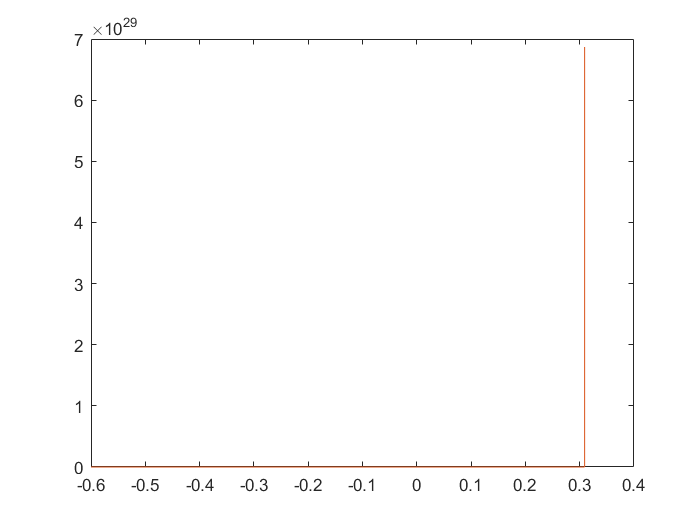

plot(sol.x, sol.y)

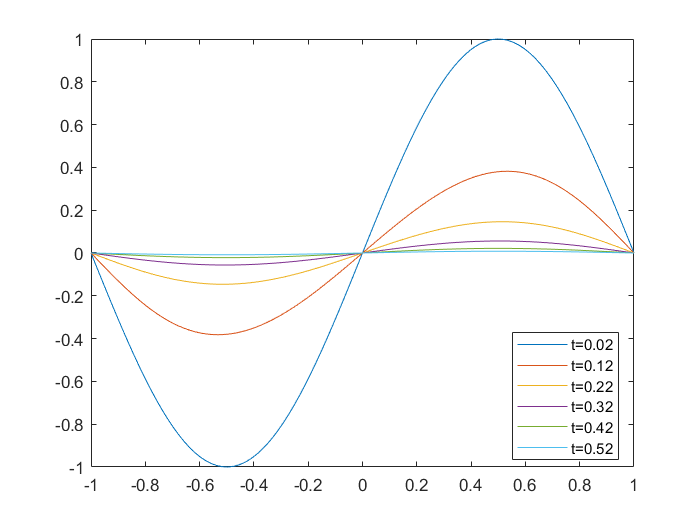

m = 0;
options = odeset('Events',@pdevents);
x = linspace(-1,1,100);
t = linspace(0.1,2,50);
[sol,tsol,sole,te,ie] = pdepe(m,@oscpde,@oscic,@oscbc,x,t,options);

figure
ii = 1:5:30;
for i = ii
    plot(x, sol(i,:))
    hold on
end
tt = ii/50;
legend('t=0.02','t=0.12', 't=0.22', 't=0.32', 't=0.42', 't=0.52', 'Location', 'best')